load('/Volumes/SanDisk/Tsunami_Fragility_Toolkit_Dev/RESCOOL/OSmodels_RESCOOL/Y_3z_9x_2y_GF0Q_F1Q_I2Q_B2Q/Y_3z_9x_2y_GF0Q_F1Q_I2Q_B2Q_tsunami_scenarios_3F_Y')
scenarios = keys(objTsunamiModel);
u = cell(numel(scenarios),1);
htsu = cell(numel(scenarios),1);
Ft_B = cell(numel(scenarios),1);
legendString = cell(numel(scenarios),1);
for scn = 1:numel(scenarios)
    scenario = objTsunamiModel(scenarios{scn});
    lateralForces = scenario('lateralForces'); 
    parameters = scenario('tsunamiParameters');
    % disp(parameters);
    u{scn} = parameters.u;
    htsu{scn} = parameters.htsu;
    Ft_B{scn} = parameters.Ft_B1;
    Fr = parameters.Fr;
    Frc = parameters.Fr_c1;
    bw = parameters.b_w1;
    legendString{scn} = ['Fr = ' num2str(Fr) '; Fr_c = ' num2str(round(Frc,2)) '; b/w = ' num2str(bw)];
end

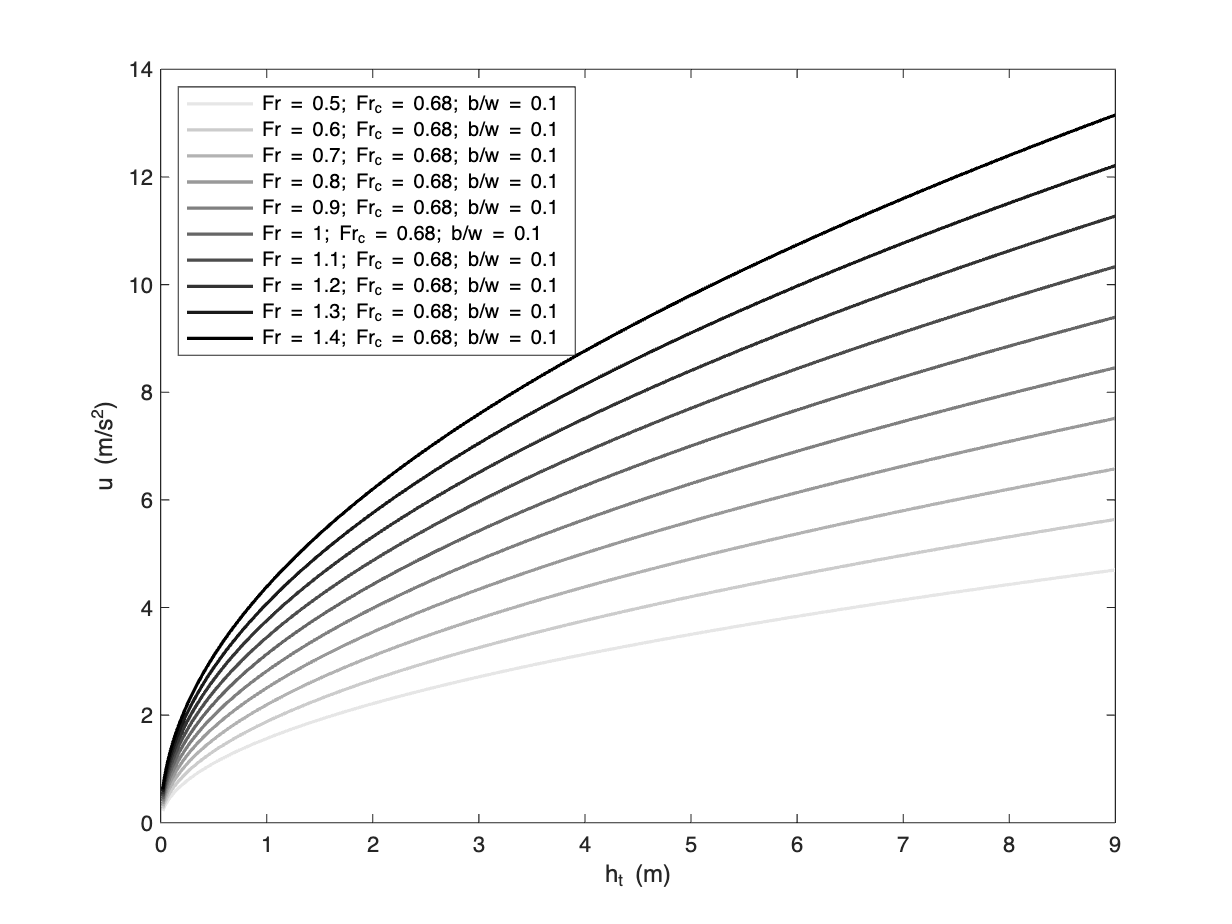

path = '/Users/jonascels/Library/CloudStorage/Dropbox/THESIS/FIGURES/';
cmap = flipud(gray(numel(scenarios)+1));
cmap = cmap(2:11,:);

fig1 = figure;
hold on
for scn = 1:numel(scenarios)
    plot(htsu{scn},u{scn},'DisplayName',legendString{scn},'Color',cmap(scn, :),'LineWidth',1.5)
end
hold off
box on
% title('Inundation Height vs. Flow Velocity under a constant Froude value')
ylabel('u (m/s^{2})','Interpreter','tex')
xlabel('h_t (m)','Interpreter','tex')
legend('Location','northwest')
exportgraphics(fig1, fullfile(path, 'tsunami-scenarios-depth-v-velocity.png'), 'Resolution', 300);

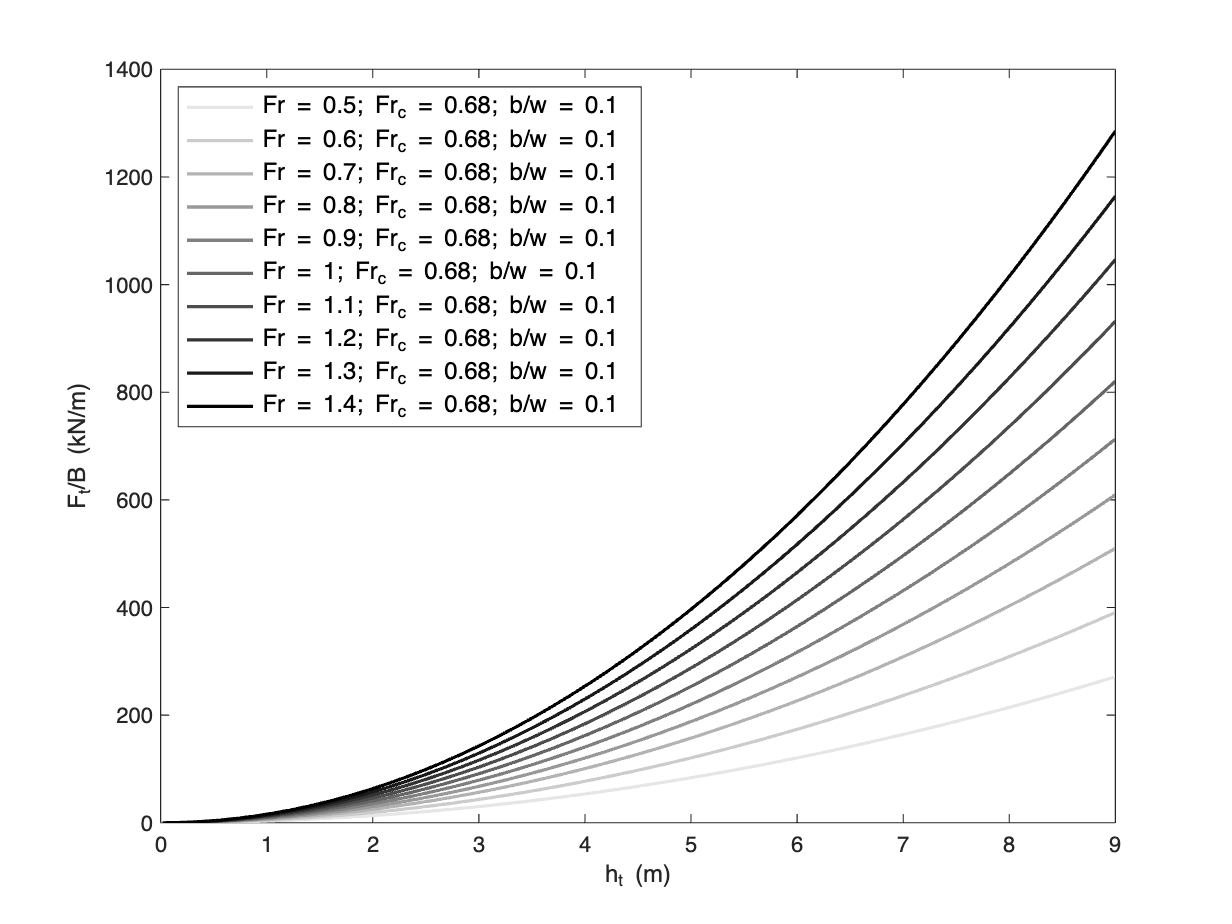

% close(fig1)

fig2 = figure;
hold on
for scn = 1:numel(scenarios)
    plot(htsu{scn},Ft_B{scn},'DisplayName',legendString{scn},'Color',cmap(scn, :),'LineWidth',1.5)
end
hold off
box on
% title('Inundation Height vs. Force per unit width under a constant Froude value')
ylabel('F_t/B (kN/m)','Interpreter','tex')
xlabel('h_t (m)','Interpreter','tex')
legend('Location','northwest','FontSize',11)
exportgraphics(fig2, fullfile(path, 'tsunami-scenarios-depth-v-force.png'), 'Resolution', 300);

% close(fig2)


